clear all
load TR4_data.mat
syms x y z
S1=[link(2)*cos(pi/4) 0 link(2)*cos(pi/4)+link(3)*cos(pi/4)]

S1 =    14.3260         0   35.5038


S3=[80 10 20];
eqn1=(x-S1(1))^2+(z-S1(3))^2-link(1)^2

$$eqn1 = {\left(x-\frac{8064811680335761}{562949953421312}\right)}^{2}+{\left(z-\frac{1249180017490309}{35184372088832}\right)}^{2}-400$$

eqn3=(x-S3(1))^2+(y-S3(2))^2+(z-S3(3))^2-link(4)^2

$$eqn3 = {\left(x-80\right)}^{2}+{\left(y-10\right)}^{2}+{\left(z-20\right)}^{2}-1600$$

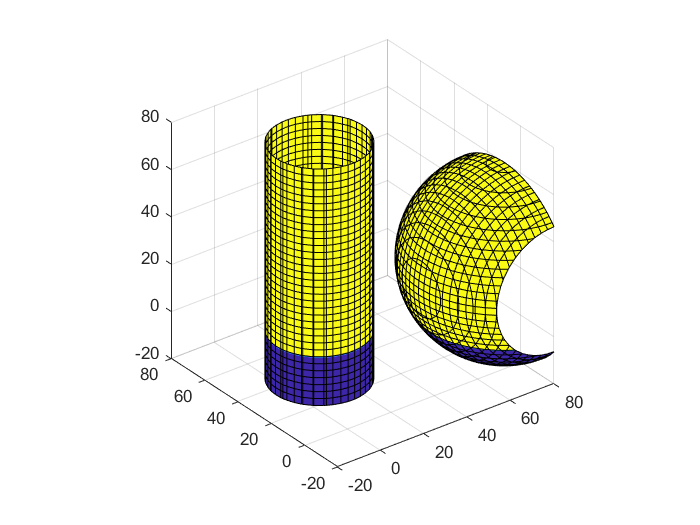

fimplicit3(eqn1)
axis("equal")
xlim([-20 80])
ylim([-20 80])
zlim([-20 80])
hold on
fimplicit3(eqn3)
plot3(S1(1),S1(3),S1(2),'o')
plot3(S3(1),S3(3),S3(2),'o')
hold off